clc;
clear all;
close all;

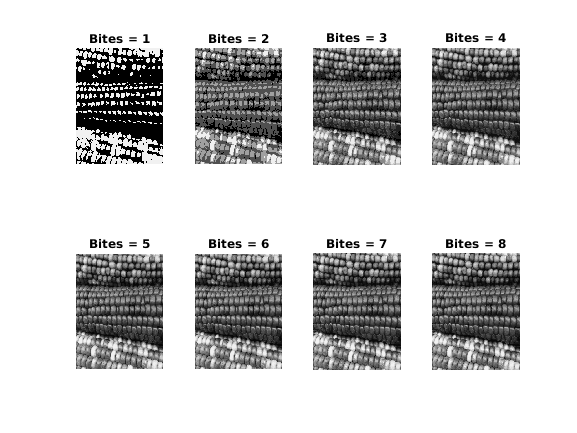

[I,map]=imread('corn.tif');
I = ind2gray(I,map);

figure
for i=1:8
    subplot(2,4,i)
    imshow(cuantificador(I,i))
    title("Bites = "+ i)
end

figure
Bits = [1; 2; 3; 4; 5; 6; 7; 8];
Ruido=zeros(8,1);
for i=1:8
    Ruido(i,1)=max(max(cuantificador(I,i)-I));
end
table(Bits,Ruido)

ans = 8×2 table
    Bits    Ruido
    ____    _____

     1       119 
     2        40 
     3        17 
     4         8 
     5         4 
     6         2 
     7         1 
     8         0 


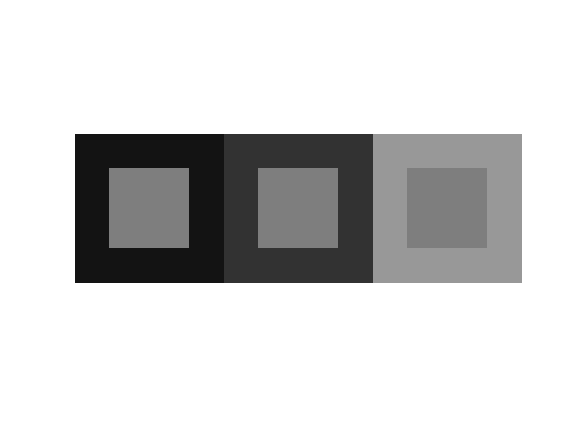

%a = [0.2 0.6 0.4 0.5];


% secciones = size(a,2)-1;
% cuadro = zeros(300,300,secciones);
% for r=1:secciones
%     cuadro(:,:,r)=cuadro(:,:,r)+a(r);
%     cuadro(70:230,70:230,r)=a(4);
% end
% L = cuadro(:,:,1);
% for i=2:secciones
%     L = cat(2, L, cuadro(:,:,i));
% end

a = [20 51 153 127];

L = ilusionoptica(a);

imshow(L,gray)

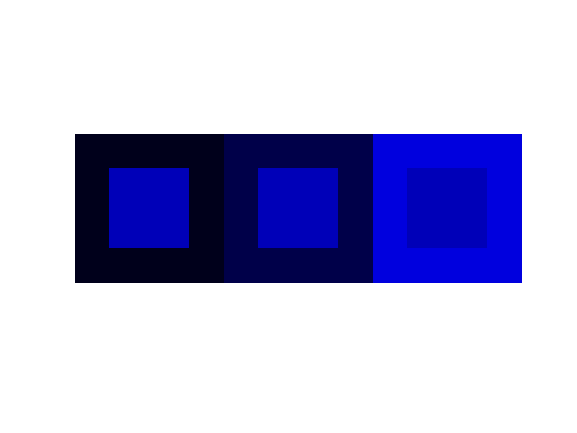

% cantidad de tonos de azul
N=175;
% secuencia de 0 a 1
s1= 0:1/(N-1):1;
%mapa de color azul
mapB=zeros(N,3);
mapB(:,3,:)=s1;
imshow(L,mapB)

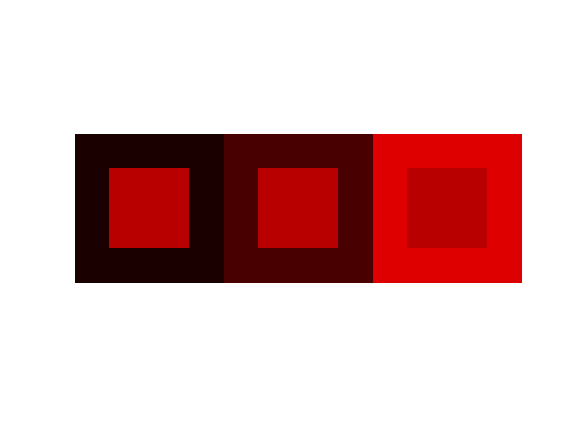

% cantidad de tonos de azul
N=175;
% secuencia de 0 a 1
s1= 0:1/(N-1):1;
%mapa de color rojo
mapR=zeros(N,3);
mapR(:,1,:)=s1;
imshow(L,mapR)

a = [20 51 153 127];

secciones = size(a,2)-1;
cuadro = zeros(300,300,secciones);
for r=1:secciones
    cuadro(:,:,r)=cuadro(:,:,r)+a(r);
    cuadro(70:230,70:230,r)=a(4);
end
Im = cat(2, cuadro(:,:,1), cuadro(:,:,2), cuadro(:,:,3));

imshow(Im,gray)

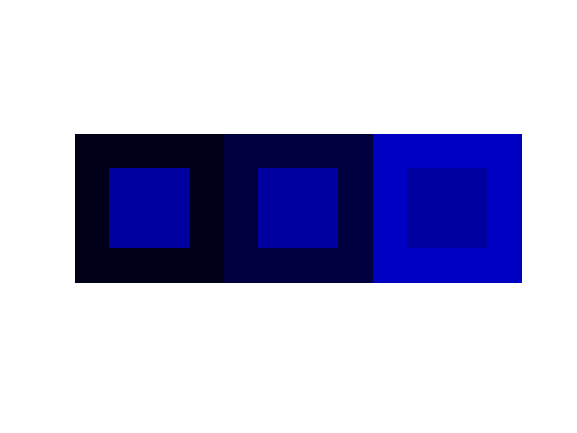

N=200;
seccuencia= 0:1/(N-1):1;
Rojo=zeros(N,3);
Azul=zeros(N,3);

Rojo(:,1)=seccuencia;
Azul(:,3)=seccuencia;

imshow(Im,Azul)

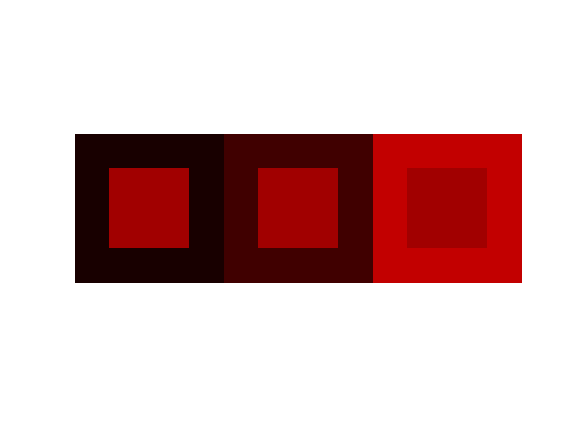

imshow(Im,Rojo)

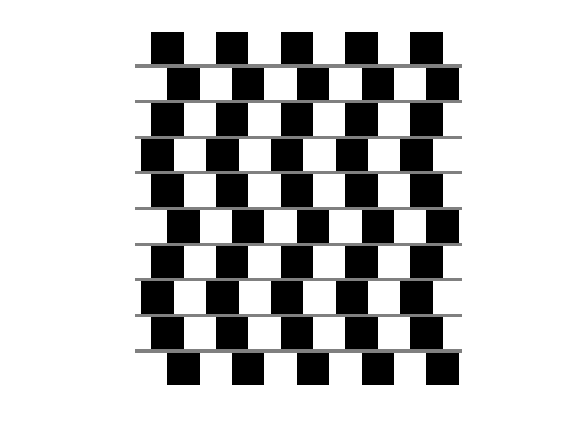

negro = zeros(10);
blanco = ones(10);
fila = cat(2, blanco, negro, blanco, negro,blanco, negro, blanco, negro,blanco, negro, blanco);
fila1 = fila(:,6:106);
fila2 = fila(:,1:101);
fila3 = fila(:,9:109);
vector = zeros(1,101);
vector = vector + 0.5;
matriz = cat(1, fila1, vector, fila2, vector, fila1, vector, fila3, vector, fila1, vector, fila2, vector, fila1, vector, fila3, vector, fila1, vector, fila2);
imshow(matriz)
colormap gray

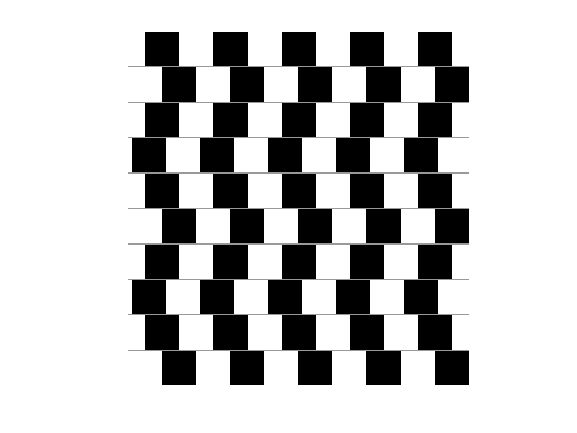

% squareB = zeros(100);
% squareW = ones(100);
% row = cat(2, squareW, squareB, squareW, squareB,squareW, squareB, squareW, squareB,squareW, squareB, squareW);
% row1 = row(:,50:1050);
% row2 = row(:,1:1001);
% row3 = row(:,90:1090);
% line = zeros(4,1001);
% line = line + 0.6;
% I = cat(1, row1, line, row2, line, row1, line, row3, line, row1, line, row2, line, row1, line, row3, line, row1, line, row2);
I = ilusion();
imshow(I)
colormap gray